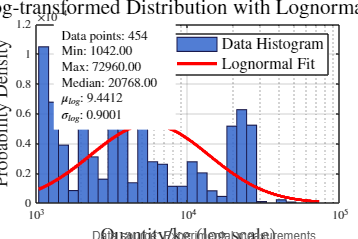

clear; clc;

data = [72960, 67500, 47052, 45000, 41824, 41680, 40000, 40000, 40000, 40000, 28550, 28550, 27792, 27500, 27482, 27482, 27482, 27482, 27482, 27482, 27482, 27482, 26876, 26876, 26140, 26140, 26140, 26140, 26140, 26140, 26140, 26140, 26140, 26140, 26140, 26140, 26140, 26140, 26140, 26140, 26140, 26140, 26140, 26140, 26140, 26140, 26140, 26140, 26140, 26140, 26140, 26140, 26140, 25968, 25968, 25930, 25856, 25856, 25786.25, 25700, 25675, 25675, 25675, 25675, 25675, 25626, 25626, 25626, 25626, 25600, 25400, 25112, 25112, 25000, 25000, 25000, 25000, 25000, 25000, 25000, 25000, 25000, 25000, 25000, 25000, 25000, 25000, 25000, 25000, 25000, 25000, 25000, 25000, 25000, 25000, 25000, 25000, 25000, 25000, 25000, 25000, 25000, 25000, 24838, 24420, 23750, 23750, 23592, 23592, 23592, 23592, 23586, 23544, 23526, 23526, 23526, 23526, 23526, 23526, 23526, 23526, 23526, 23526, 23526, 23526, 23526, 23526, 23526, 23525.96, 23525.96, 23490, 23490, 23300, 23300, 23208, 23200, 23200, 23200, 23200, 23200, 23200, 23200, 23162.18, 23161.8, 23161.8, 23161.8, 23161.8, 22750, 22750, 22504, 22504, 22504, 22504, 22500, 22500, 22470, 22280, 22090, 22090, 22000, 21890, 21694, 21600, 21543, 21543, 21500, 21500, 21278, 21163, 21160, 21160, 21160, 21160, 21160, 21160, 21160, 21160, 21160, 21160, 21160, 21160, 21120, 21120, 21120, 21107, 21080, 21080, 21080, 21080, 21080, 21080, 21080, 21080, 21080, 21080, 21080, 21080, 20954, 20950, 20933, 20930, 20928, 20928, 20928, 20920, 20912, 20912, 20912, 20912, 20912, 20912, 20912, 20912, 20912, 20912, 20912, 20912, 20912, 20912, 20912, 20912, 20912, 20896, 20792, 20785, 20768, 20768, 20768, 20768, 20476, 20476, 20076, 20076, 20000, 20000, 20000, 20000, 20000, 20000, 20000, 20000, 20000, 20000, 20000, 20000, 20000, 20000, 20000, 20000, 20000, 19984, 19646, 19575, 19575, 19575, 19575, 19575, 19575, 19575, 19575, 19574.8, 19574.8, 19574.8, 19574.8, 19574.8, 19574.8, 19574.8, 19220, 19038, 17500, 16000, 16000, 16000, 15506, 15000, 14734.7, 14476, 14476, 14301, 14000, 14000, 13750, 13000, 13000, 12620, 12500, 12500, 12500, 12500, 12500, 12500, 12500, 12500, 12500, 12500, 12500, 12000, 12000, 12000, 11000, 10580, 10400, 10000, 10000, 10000, 10000, 10000, 10000, 10000, 10000, 10000, 10000, 10000, 10000, 10000, 10000, 10000, 10000, 10000, 9750, 9600, 9600, 9178.75, 9149, 9037, 8750, 8130, 8000, 8000, 7842, 7842, 7500, 7000, 7000, 7000, 7000, 7000, 6603.13, 6603.13, 6592.5, 6535, 6535, 6535, 6320, 6252, 6250, 6250, 6250, 6250, 6000, 6000, 6000, 6000, 6000, 6000, 5320, 5310, 5310, 5270, 5270, 5228, 5228, 5210, 5210, 5000, 5000, 5000, 5000, 5000, 5000, 5000, 5000, 5000, 5000, 5000, 5000, 4743, 4500, 4494, 4232, 4232, 4000, 4000, 4000, 4000, 4000, 4000, 3921, 3921, 3921, 3921, 3921, 3907.5, 3907.5, 3750, 3750, 3750, 3750, 3750, 3750, 3696, 3500, 3500, 3102, 3000, 3000, 3000, 3000, 3000, 3000, 3000, 3000, 3000, 3000, 3000, 3000, 2633, 2614, 2605, 2500, 2500, 2500, 2500, 2500, 2160, 2143.02, 2000, 2000, 2000, 2000, 2000, 2000, 2000, 2000, 2000, 1750, 1587, 1500, 1500, 1500, 1350, 1340.5, 1307, 1307, 1250, 1250, 1080, 1058, 1058, 1051.52, 1051.52, 1042, 1042, 1042, 1000, 1000, 1000, 1000, 1000, 1000, 1000, 1000, 1000, 1000, 1000, 1000, 1000, 1000, 500, 500, 500, 400, 262.5, 250, 250, 250, 183, 96.09, 50];

% 过滤数据
data = data(data > 10^3);

% 启用LaTeX和抗锯齿
set(groot, 'DefaultTextInterpreter', 'latex');
set(groot, 'DefaultAxesTickLabelInterpreter', 'latex');
set(groot, 'DefaultLegendInterpreter', 'latex');

% 创建图形
figure('Color', 'w');
set(gcf, 'Position', [100, 100, 900, 600]);

% 主绘图区域
main_ax = axes('Position', [0.1, 0.15, 0.85, 0.75]);

% 使用对数变换处理数据
log_data = log(data);
bin_width = 0.15; % 对数空间的bin宽度
edges = exp(min(log_data):bin_width:max(log_data));
bin_centers = sqrt(edges(1:end-1) .* edges(2:end)); % 几何中心

% 方法1：基于直方图的近似计算（快速但精度一般）
[counts, edges] = histcounts(data, 'Normalization', 'pdf');
bin_width = edges(2) - edges(1);
bin_centers = edges(1:end-1) + bin_width/2;  % 更精确的中心点计算

% 找到完全包含[1000,10000]的bins
valid_bins = (edges(1:end-1) >= 21000) & (edges(2:end) <= 24000);
prob_hist = sum(counts(valid_bins) * bin_width)



% 绘制直方图
histogram('BinEdges', edges, 'BinCounts', histcounts(data, edges), ...
    'Normalization', 'pdf', ...
    'FaceColor', [0.2, 0.4, 0.8], ...
    'EdgeColor', [0.1, 0.1, 0.3], ...
    'FaceAlpha', 0.85, ...
    'LineWidth', 0.8);
hold on;

% 对数正态分布拟合
pd_logn = fitdist(data', 'Lognormal');
x = linspace(min(data), max(data), 1000);
y_log = pdf(pd_logn, x);
plot(x, y_log, 'r-', 'LineWidth', 2.5);

% 设置对数坐标轴
set(gca, 'XScale', 'log');
grid on;
box on;

% 标签和图例
xlabel('Quantity/kg (log scale)', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('Probability Density', 'FontSize', 14, 'FontWeight', 'bold');
title('Log-transformed Distribution with Lognormal Fit', 'FontSize', 16);
legend({'Data Histogram', 'Lognormal Fit'}, ...
    'Location', 'northeast', 'FontSize', 12);

% 添加数据统计信息
stats_str = {
    sprintf('Data points: %d', length(data)), ...
    sprintf('Min: %.2f', min(data)), ...
    sprintf('Max: %.2f', max(data)), ...
    sprintf('Median: %.2f', median(data)), ...
    sprintf('$\\mu_{log}$: %.4f', pd_logn.mu), ...
    sprintf('$\\sigma_{log}$: %.4f', pd_logn.sigma)
};
annotation('textbox', [0.15, 0.75, 0.2, 0.15], ...
    'String', stats_str, ...
    'FitBoxToText', 'on', ...
    'BackgroundColor', [1, 1, 1, 0.7], ...
    'EdgeColor', 'none', ...
    'FontSize', 10, ...
    'Interpreter', 'latex');

% 添加数据源和说明
annotation('textbox', [0.5, 0.02, 0.4, 0.04], ...
    'String', 'Data source: Experimental measurements', ...
    'FitBoxToText', 'on', ...
    'EdgeColor', 'none', ...
    'HorizontalAlignment', 'right', ...
    'FontSize', 9, ...
    'Color', [0.4, 0.4, 0.4]);

% 保存高分辨率图像
print(gcf, 'optimized_distribution_plot', '-dpng', '-r300');